## Ejemplo: Estimar el valor de $ln(2)$ usando la interpolación de Newton

Recordando los términos de los coeficientes del polinómio de Newton hasta el grado 3:

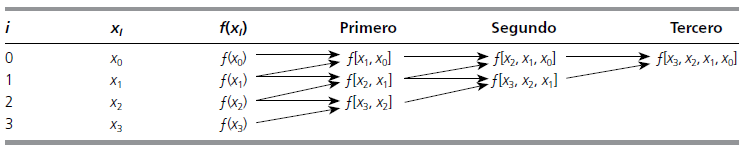

donde la primera diferencia finita $f[x_i,x_j]=\frac{f(x_i)-f(x_j)}{x_i-x_j}$, la segunda diferencia finida $f[x_i,x_j,x_k]=\frac{f[x_i,x_j]-f[x_j,x_k]}{x_i-x_k}$

Aproximamos el valor de $ln(2)$ usando iterpolación de Newton a partir de conocer los valores de $ln(1)$ y $ln(6)$.

clc;
clear;

% Valores conocidos
x = [1, 6];
y = log(x);

% Diferencias divididas de Newton
n = length(x);
div_diff = zeros(n, n);
div_diff(:, 1) = y';

for j = 2:n
    for i = j:n
        div_diff(i, j) = (div_diff(i, j-1) - div_diff(i-1, j-1)) / (x(i) - x(i-j+1));
    end
end

% Coeficientes del polinomio de Newton
coeff = div_diff(n, :)

% Evaluar el polinomio en x = 2
x_approx = 2;
P = coeff(n);
for k = n-1:-1:1
    P = P * (x_approx - x(k)) + coeff(k);
end

% Mostrar el resultado
fprintf('La aproximación de ln(2) usando interpolación de Newton es: %.15f\n', P);

La aproximación de ln(2) usando interpolación de Newton es: 2.150111363073666


Ahora usando dos tres puntos

% Definir los puntos conocidos
x = [1,4,6];
y = log(x);

% Número de puntos
n = length(x);

% Inicializar la tabla de diferencias divididas
divided_diff_table = zeros(n, n);
divided_diff_table(:, 1) = y';

% Calcular las diferencias divididas
for j = 2:n
    for i = 1:(n-j+1)
        divided_diff_table(i, j) = (divided_diff_table(i+1, j-1) - divided_diff_table(i, j-1)) / (x(i+j-1) - x(i));
    end
end

% Coeficientes del polinomio de Newton
coefficients = divided_diff_table(1, :);

% Aproximar ln(2) usando el polinomio de interpolación de Newton
x_target = 2;
approx_ln2 = coefficients(1);
product_term = 1;

for i = 2:n
    product_term = product_term * (x_target - x(i-1));
    approx_ln2 = approx_ln2 + coefficients(i) * product_term;
end

% Mostrar el resultado
fprintf('Aproximación de ln(2) usando interpolación de Newton: %.15f\n', approx_ln2);

Aproximación de ln(2) usando interpolación de Newton: 0.565844346900983


## Con Lagrange

% Definir los puntos de datos (x, y)
% Puedes ajustar estos puntos según sea necesario
x = [1, 4, 6];
y = log(x);

% Punto en el que se desea estimar ln(2)
x_est = 2;

% Inicializar el valor estimado
ln2_est = 0;

% Calcular el polinomio de Lagrange
n = length(x);
for i = 1:n
    % Calcular el término de Lagrange L_i(x)
    L_i = 1;
    for j = 1:n
        if j ~= i
            L_i = L_i * (x_est - x(j)) / (x(i) - x(j));
        end
    end
    % Sumar el término correspondiente al valor de y
    ln2_est = ln2_est + y(i) * L_i;
end

% Mostrar el resultado
fprintf('El valor estimado de ln(2) usando interpolación de Lagrange es: %.10f\n', ln2_est);

El valor estimado de ln(2) usando interpolación de Lagrange es: 0.5658443469


fprintf('El valor verdadero de ln(2) es: %.10f\n', log(2));

El valor verdadero de ln(2) es: 0.6931471806


fprintf('El error relativo es: %.10f%%\n', abs((ln2_est - log(2)) / log(2)) * 100);

El error relativo es: 18.3659166811%
